file = "D:\Whale Data\False Bay whale songs\song 5.wav";
% file = "D:\Whale Data\Brydes Whale 20220719\6252.211114000012_7.wav";
% file = "D:\Whale Data\Brydes Whale 20220719\6252.211114000012_8.wav";
% file = "D:\Whale Data\POIData\1\20220901_033138_8240.wav"
% file = "D:\Whale Data\2022\POI\20220816_074413_POI_LF_ALL.wav";
[x, fs] = audioread(file);
x = resample(x, 1, fs/2000);
gpuDevice(1); %reset GPU
% x = x((1:2^18) + 15*2^18);
fb = SFB(16, 0.05, 2000, numel(x), 25, 1000);
s = fb.filterS(x);
s = fb.filterS(x);
s = s.^2;
t = fb.getTime(s);
fc = fb.fc;

dl = DataLoader(1);

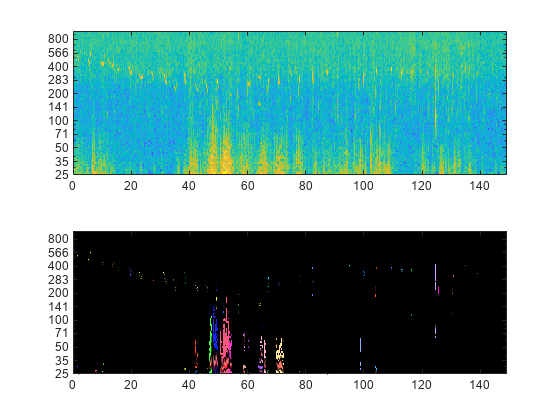

% [s, info] = dl.loadSpectrogram(10428+8);
% t = dl.fb.getTime(s);
% fc = dl.fb.fc;

% [x, info2] = dl.loadAudio(653);

% info2

% x = x{7};

% fb = SFB(16, 0.05, 2000, numel(x), 25, 1000);
% s = fb.filterS(x);
% s = s.^2;
% t = fb.getTime(s);
% fc = fb.fc;

ct = Contours(t, fc, s, "", true);

figure
ax1 = subplot(211);
imagesc(t, fb.fc, log(ct.S))
set(gca, "Ydir", "normal");
set(gca, "Yscale", "log");
yticks(round(fb.fc(1:8:end),0))
colormap(ax1, "default")



ct.connect()
ct.removeShortContours()
ct.removeHarmonics()
ct.calculateFeatures()
ct.fillContourMap()

map =  rand(numel(ct.Cdata)*4, 3);
map = rgb2hsv(map);
map(:, 3) = min(map(:, 3) + 0.5, 1);
map = hsv2rgb(map);
map(1,:) = 0;

ax2 = subplot(212);
imagesc(t, fb.fc, ct.Scont)
set(gca, "Ydir", "normal");
set(gca, "Yscale", "log");
yticks(round(fb.fc(1:8:end),0))
colormap(ax2, map)
linkaxes([ax1, ax2]);
ylim([min(fb.fc) max(fb.fc)])
hold on
for c = ct.Cdata
    tpl = t(c.tmin:c.tmax);
    plot(tpl, c.f0, "w")
    bwu = c.f0 + c.bw;
    bwl = fliplr(c.f0 - c.bw);
    bwpl = [bwu, bwl];
    tbw = [tpl, fliplr(tpl)];
    fill(tbw, bwpl, "red", "FaceAlpha",0.5);
end
hold off